% Clear environment
clear; clc;

%% REGRESSION EXAMPLE %%

% generate sample data
X = linspace(-10, 10, 20)';  % 20 points from -10 to 10
Y = 5*X.^2 + 3*X + 2 + randn(size(X))*20;  % quadratic equation with some noise

% Number of coefficients (for a quadratic fit we need 3 coefficients)
numCoeffs = 3;

% fit the polynomial using the custom function
coeffs = polynomialFit(X, Y, numCoeffs);

P =     5.0067
    2.1751
    1.1678



% display the coefficients
fprintf('The fitted polynomial coefficients are:\n');

The fitted polynomial coefficients are:


disp(coeffs);

    5.0067
    2.1751
    1.1678



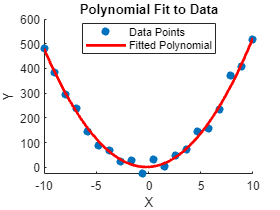


% plot the original data and the fitted polynomial
scatter(X, Y, 'filled');
hold on;

% create a dense grid for a smoother plot
xFine = linspace(min(X), max(X), 100);
% evaluate the polynomial at the grid points
yFit = polyval(coeffs, xFine);
plot(xFine, yFit, '-r', 'LineWidth', 2);
title('Polynomial Fit to Data');
xlabel('X');
ylabel('Y');
legend('Data Points', 'Fitted Polynomial', 'Location', 'Best');
hold off;



%%P CA EXAMPLE %%
data = rand(100, 5);  % Generate some random data
[loadings, explainedVariance, cumulativeVariance] = principalca(data, 0.50);

Loadings (Principal Component weights) mapped to original columns:
Component 1:
    0.4003
    0.4584
    0.6490
   -0.2693
   -0.3687

Component 2:
    0.1546
   -0.6006
    0.0561
    0.3201
   -0.7140

Component 3:
    0.5547
   -0.3053
   -0.3799
   -0.6729
    0.0454

Explained Variance by each Principal Component:
    0.2448
    0.2143
    0.2038

Cumulative Variance explained by selected components:
    0.6630





%% RANK NORMAL EXAMPLE %%
A = [1 2 3;
    4 5 6;
    7 8 9]; %non invertible rank 2 matrix

[P, Q, R] = rankNormalForm(A)

P =          0   -2.6667    1.6667
         0    2.3333   -1.3333
    1.0000   -2.0000    1.0000


Q =      0     0     1
     2     1    -2
    -1     0     1


R =     1.0000    0.0000   -0.0000
    0.0000    1.0000   -0.0000
         0         0         0


A*[1 -2 1]' %testing if right of q is in nullspace

ans =      0
     0
     0


%here, P holds the conditions on what is a 
% linear combination in the last m-rank(A) rows
% Q holds the null space in the right n-rank(A) columns
